# Eigenmode of Metallic Transmission Line

**Metallic transmission lines**, often employed in plasmonics and microwave engineering, support modes with strong field confinement and unique dispersion properties due to their interaction with the metal-dielectric boundary.

The eigenmode solver computes the guided modes supported by the transmission line, including their field profiles and effective indices, providing valuable insights into the wave propagation characteristics of the structure.

% physics constant
eps0 = Constant('eps0').v; % permittivity in vacuum
c0 = Constant('c0').v; % light speed in vacuum

### Step 0: Global Settings

The simulation begins by initializing the `Model2D` instance and configuring the global settings. These parameters establish the foundational setup for the simulation. The working plane is defined as the $\mathit{\mathbf{x}}-\mathit{\mathbf{y}}$** plane.**

modelTL = Model2D.initialize();

Model2D: Object Initialized


modelTL.setLabel('yz'); % work on y-z plane

### Step 1: Simulation device

This step constructs the simulation domain by defining the geometry and assigning material properties to the air background, conductors, and substrate. Each component is added to the model as a separate device.

#### 1.1 Geometry parameters

The geometry of the metallic transmission line is defined by the dimensions of its simulation domain, conductive layers, and substrate. These parameters ensure an accurate representation of the transmission line's structure within the simulation.

% size parameters
um = 1e-6; % unit correction factor
W = 3200*um;
H = 800*um;
d_cond_down = 100*um;
d_substrate = 500*um;
d_cond_up = 35*um;
w_cond_up = 1000*um;

#### 1.2 Metal material information

Because the conductor is made of metals, its complex relative permittivity is depended on frequency of transfered wave, $\tilde{\varepsilon_r}=1+\frac{\sigma}{i\omega\varepsilon_0}$. The operating frequency is set to be **1 GHz. **

The substrate material FR-4 also has lossy property, so that its complex relative permittivity can be defined as $\tilde{\varepsilon_r}=\varepsilon_r(1-i\tan\delta)$.

f = 1e9; % frequency, unit: Hz

% cooper conductor
sigma = 5.8e7; % conductivity
eps_cond = 1 + sigma/(1i*2*pi*f*eps0);

% FR-4 substrate
eps0_sub = 4.4; 
tand  = 0.03;
eps_sub = eps0_sub*(1 - 1i*tand);

#### 1.3 Cooper conductor

The conductors are modeled as two rectangles:

- The lower conductor is placed at the base of the simulation domain.

- The upper conductor is positioned above the substrate at the specified offset.

% lower conductor
modelTL.addDevice(1);
modelTL.setDevice(1).setGeometry('Rectangle', W, d_cond_down, 'bl', [-W/2, 0]);
modelTL.setDevice(1).setMaterial(eps_cond);

% upper conductor
modelTL.addDevice(2);
modelTL.setDevice(2).setGeometry('Rectangle', w_cond_up, d_cond_up, 'bl', [-w_cond_up/2, d_cond_down+d_substrate]);
modelTL.setDevice(2).setMaterial(eps_cond);

#### 1.4 FR-4 substrate

The substrate is positioned between the upper and lower conductors, filling the gap with its lossy material properties.

modelTL.addDevice(3);
modelTL.setDevice(3).setGeometry('Rectangle', W, d_substrate, 'bl', [-W/2, d_cond_down]);
modelTL.setDevice(3).setMaterial(eps_sub);

#### 1.5 Build up real device

Once all components are added, the `finishDevice` method finalizes the setup, and `dispImg` provides a visual representation of the constructed geometry.

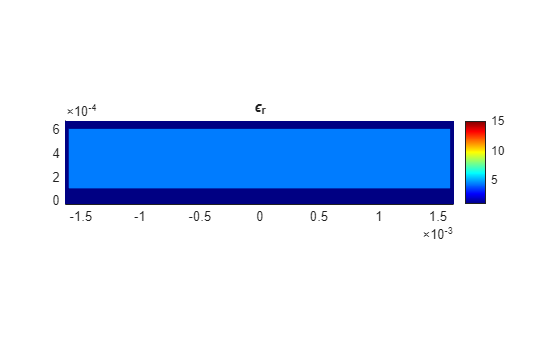

modelTL.assembleDevice;
modelTL.device.dispImg; % real part

### Step 2: FDFD region mesh grid

The FDFD solver operates on a uniform mesh grid to discretize the simulation domain. Before meshing, the geometry is represented as a `polyshape` object. After meshing, it transforms into a discrete double array that captures the spatial distribution of relative permittivity $\varepsilon_r$ and relative permeability $\mu_r$.

% grid size
Ny = 151; 
Nz = 201;

dy = 20*um; % unit: um
dz = 5*um;

% set mesh grid
modelTL.setMesh([Ny, Nz], [dy, dz]);
modelTL.shiftMesh('z', 'c', 400*um);

% mesh device
modelTL.meshDevice;

### Step 3: Configure solver

#### 3.1 Set wavelength

Based on operating frequency set above, wavelength of this eigenmode problem is approximately **0.2998 m**.

wavelength = c0/f;
modelTL.setWavelength(wavelength); % work at 0.2998 m wavelength

#### 3.2 Set up FDFD eigenmode solver

The simulation requires a solver to calculate the electromagnetic fields and eigenmodes of the metallic transmission line. In this example, the `EigenMode `solver is selected, which is specifically designed to compute the guided modes supported by the structure. This solver analyzes the field distribution and effective indices of the eigenmodes.

The simulation computes the **fundamental eigenmode** of the metallic transmission line. The fundamental mode represents the primary guided mode supported by the structure, with its field distribution determined by solving the eigenmode equation.

num_mode = 1; % fundamental mode
modelTL.setSolver('EigenMode', num_mode);

### Step 4: Solve eigenmode

modelTL.solveModel;

Model object has been solved successfully.


modelTL.dispInfo;

=== Model2D Information ===
Wavelength   : 2.998e-01 m
Plane Label  : yz
Background   : eps_r=1.000, mu_r=1.000
Mesh         : y: N=151, d=2.000e-05 m
               z: N=201, d=5.000e-06 m
Solver       : EigenMode
Requested Modes: 1
Modes and neff:
   Mode 1 : neff = 1.549973 -0.018336i


The computed eigenmode is visualized. This helps verify the mode shape and confinement properties.

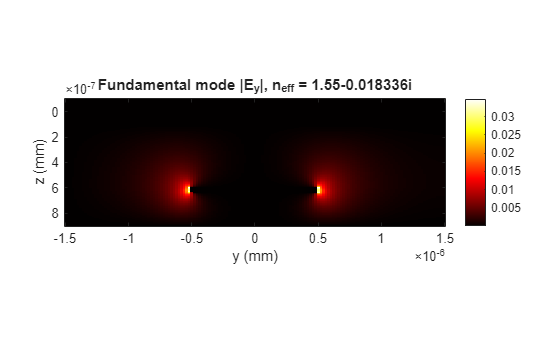

results = modelTL.exportResults;

figure;
imagesc(results.y*1e-3, results.z*1e-3, abs(results.Ey(:,:,1)).');
xlabel('y (mm)'), ylabel('z (mm)'); axis image;
colormap hot; colorbar;
title(['Fundamental mode |E_y|, n_{eff} = ', num2str(results.neff(1))]);

The simulated field distribution of the **fundamental eigenmode** appears as expected, with strong confinement around the conductive regions of the transmission line. The symmetric field profile and smooth intensity gradients confirm the efficient guiding of electromagnetic waves in the metallic structure. The results align well with theoretical predictions, demonstrating the accuracy and reliability of the FDFD EigenMode solver for analyzing metallic transmission lines.